# Trabajo práctico: Filtrado FIR

### Ejercicio 1

clear, clc;
freqn_hz = 100; %[hz]
freq_s = 1200;
t_s = 1/freq_s;
t_0 = 0;
t_f = 0.2;
n = t_0:t_s:t_f;
x = sin(2*pi*freqn_hz*n);
target_snr = 15; %[dB]
noisy_x = awgn(x, target_snr,"measured");
freq_co = 2*freqn_hz;
F_co = freq_co/freq_s;
N_max = ceil(1/(2*F_co)); % max window size
N = N_max;
b = (1/N)*ones(1,N);
a = 1;
filtered_x_N_max = filter(b,a,noisy_x);
N_half = ceil(N_max/2);
b_half = (1/N_half)*ones(1,N_half);
filtered_x_half_N_max = filter(b_half,a,noisy_x);
N_ten = 10*N_max;
b_ten = (1/N_ten)*ones(1,N_ten);
filtered_x_ten_N_max = filter(b_ten,a,noisy_x);

Respuesta en frecuencia y fase del filtro MA.

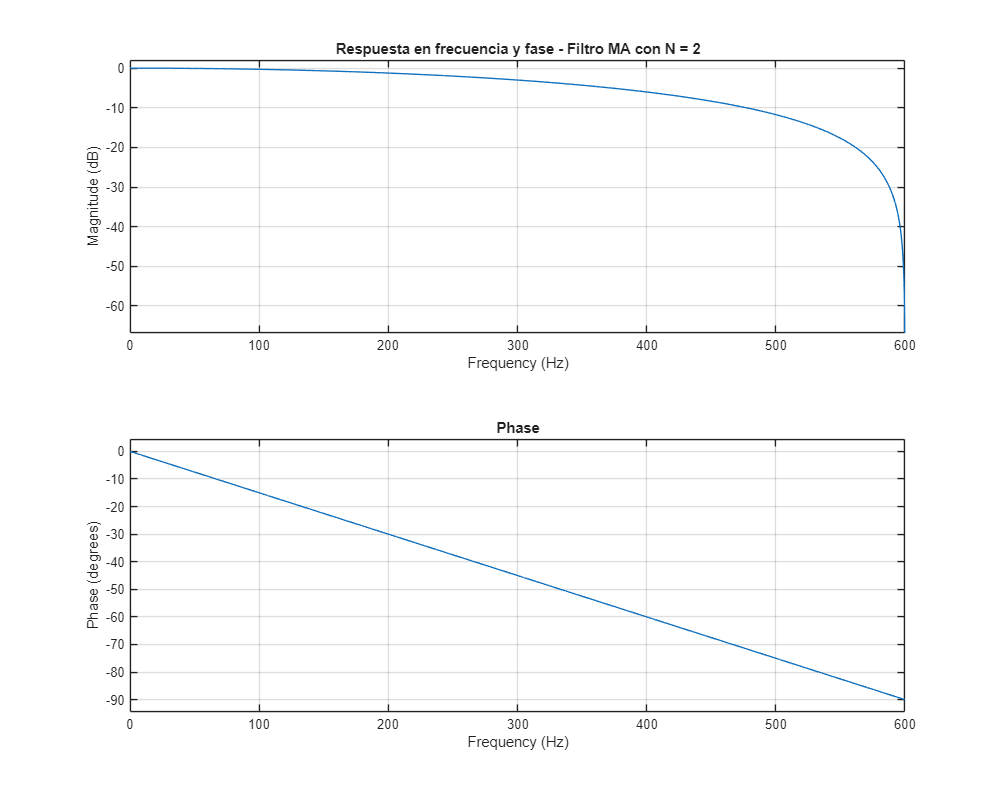

[H_half,f] = freqz(b_half,a,4096,freq_s);
mag_dB_half = 20*log10(abs(H_half));
idx_half = find(mag_dB_half <= -3, 1, 'first');
f_cut_half = f(idx_half);

[H_full,~] = freqz(b,a,4096,freq_s);
mag_dB_full = 20*log10(abs(H_full));
idx_full = find(mag_dB_full <= -3, 1, 'first');
f_cut_full = f(idx_full);

[H_ten,~] = freqz(b_ten,a,4096,freq_s);
mag_dB_ten = 20*log10(abs(H_ten));
idx_ten = find(mag_dB_ten <= -3, 1, 'first');
f_cut_ten = f(idx_ten);

figure('Position',[100 100 1000 800]);
freqz(b_half, a, 4096, freq_s);
title(['Respuesta en frecuencia y fase - Filtro MA con N = ', num2str(N_half)]);

disp(['Frecuencia de corte real para N = N_max/2: ', num2str(f_cut_half), ' Hz']);

Frecuencia de corte real para N = N_max/2: 299.5605 Hz


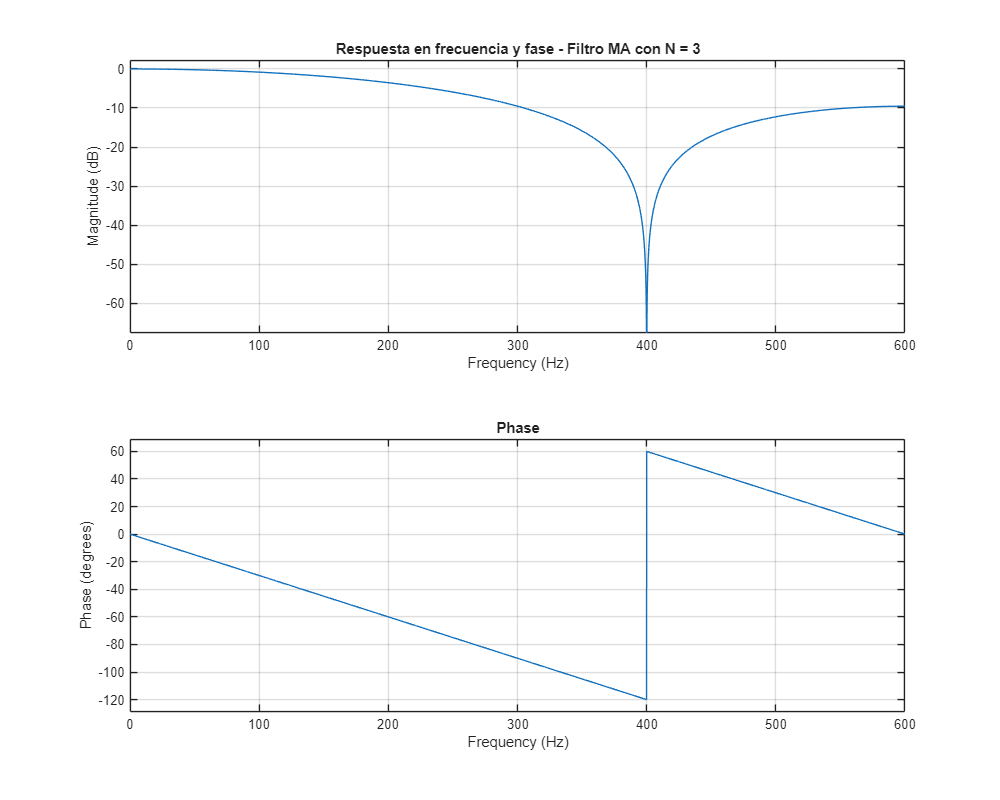

freqz(b, a, 4096, freq_s);
title(['Respuesta en frecuencia y fase - Filtro MA con N = ', num2str(N_max)]);

disp(['Frecuencia de corte real para N = N_max: ', num2str(f_cut_full), ' Hz']);

Frecuencia de corte real para N = N_max: 186.1816 Hz


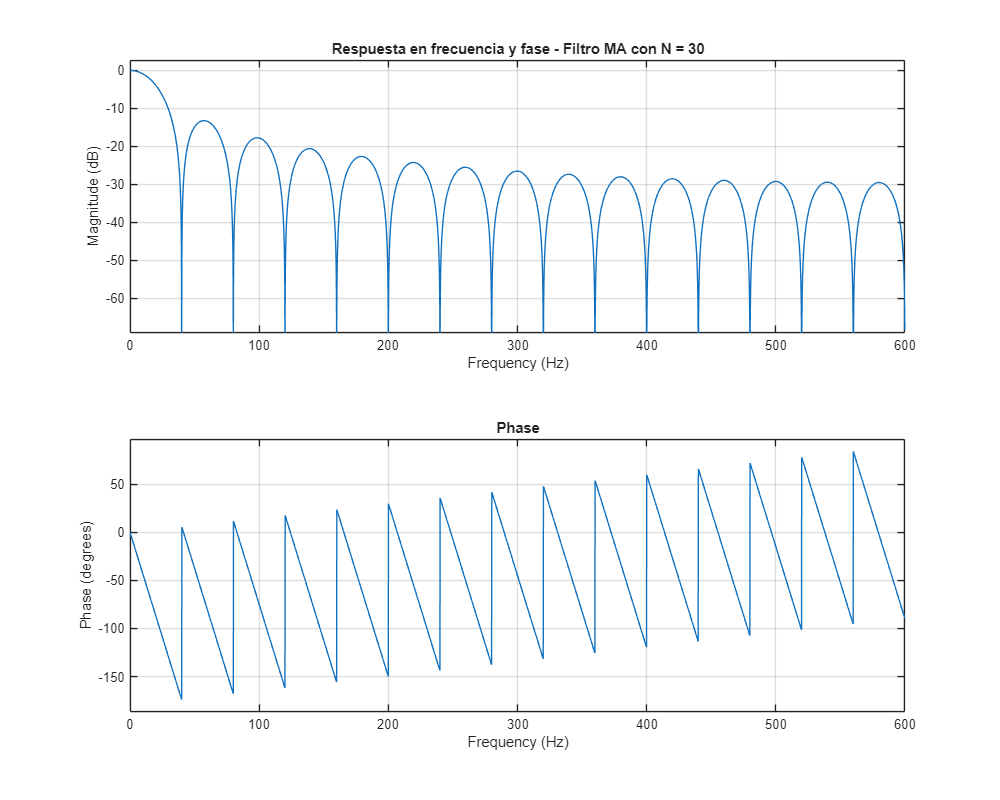

freqz(b_ten, a, 4096, freq_s);
title(['Respuesta en frecuencia y fase - Filtro MA con N = ', num2str(N_ten)]);

disp(['Frecuencia de corte real para N = 10*N_max: ', num2str(f_cut_ten), ' Hz']);

Frecuencia de corte real para N = 10*N_max: 17.7246 Hz


Señales en el dominio del tiempo

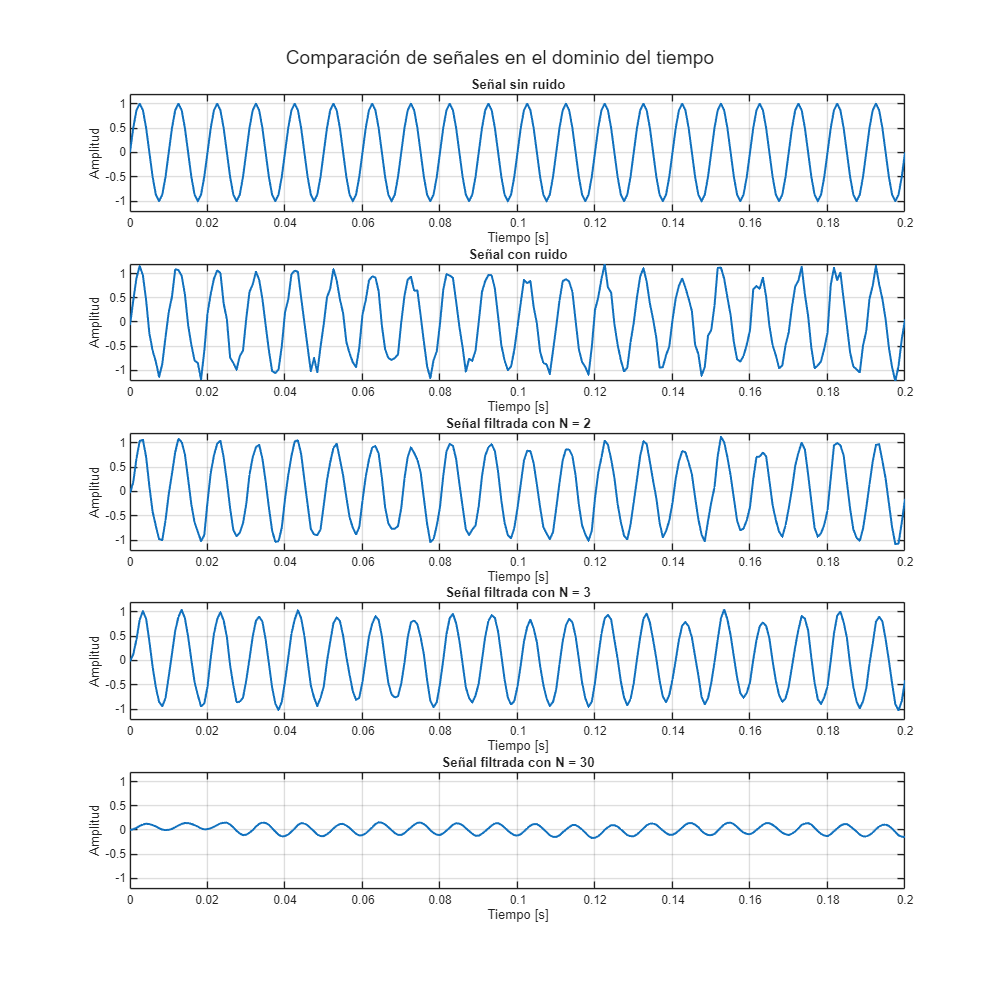

figure('Position',[100 50 1000 1000]);

yl = [min([x noisy_x filtered_x_half_N_max filtered_x_N_max filtered_x_ten_N_max]) ...
      max([x noisy_x filtered_x_half_N_max filtered_x_N_max filtered_x_ten_N_max])];

subplot(5,1,1);
plot(n, x, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal sin ruido');

subplot(5,1,2);
plot(n, noisy_x, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal con ruido');

subplot(5,1,3);
plot(n, filtered_x_half_N_max, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal filtrada con N = ', num2str(ceil(N_max/2))]);

subplot(5,1,4);
plot(n, filtered_x_N_max, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal filtrada con N = ', num2str(N_max)]);

subplot(5,1,5);
plot(n, filtered_x_ten_N_max, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal filtrada con N = ', num2str(10*N_max)]);

sgtitle('Comparación de señales en el dominio del tiempo');

% SNR de entrada
noise_in = noisy_x - x;
snr_in = 10*log10(sum(x.^2)/sum(noise_in.^2));

%% SNR de salida para N = ceil(N_max/2)
N = ceil(N_max/2);
delay = floor((N-1)/2);

x_aligned = x(1:end-delay);
filtered_aligned = filtered_x_half_N_max(delay+1:end);

noise_out = filtered_aligned - x_aligned;
snr_out_half = 10*log10(sum(x_aligned.^2)/sum(noise_out.^2));

%% SNR de salida para N = N_max
N = N_max;
delay = floor((N-1)/2);

x_aligned = x(1:end-delay);
filtered_aligned = filtered_x_N_max(delay+1:end);

noise_out = filtered_aligned - x_aligned;
snr_out_max = 10*log10(sum(x_aligned.^2)/sum(noise_out.^2));

%% SNR de salida para N = 10*N_max
N = 10*N_max;
delay = floor((N-1)/2);

x_aligned = x(1:end-delay);
filtered_aligned = filtered_x_ten_N_max(delay+1:end);

noise_out = filtered_aligned - x_aligned;
snr_out_ten = 10*log10(sum(x_aligned.^2)/sum(noise_out.^2));

%% Mostrar resultados
disp(['SNR de entrada              = ', num2str(snr_in), ' dB']);

SNR de entrada              = 15.3598 dB


disp(['SNR de salida N=N_max/2    = ', num2str(snr_out_half), ' dB']);

SNR de salida N=N_max/2    = 10.6597 dB


disp(['SNR de salida N=N_max      = ', num2str(snr_out_max), ' dB']);

SNR de salida N=N_max      = 17.683 dB


disp(['SNR de salida N=10*N_max   = ', num2str(snr_out_ten), ' dB']);

SNR de salida N=10*N_max   = 1.1078 dB


Para valores grandes de N, el filtro de media móvil introduce una fuerte atenuación en la señal útil, ya que su frecuencia se encuentra dentro de la banda de rechazo del filtro. Como consecuencia, aunque el ruido se reduce, la distorsión de la señal provoca una degradación significativa del SNR.

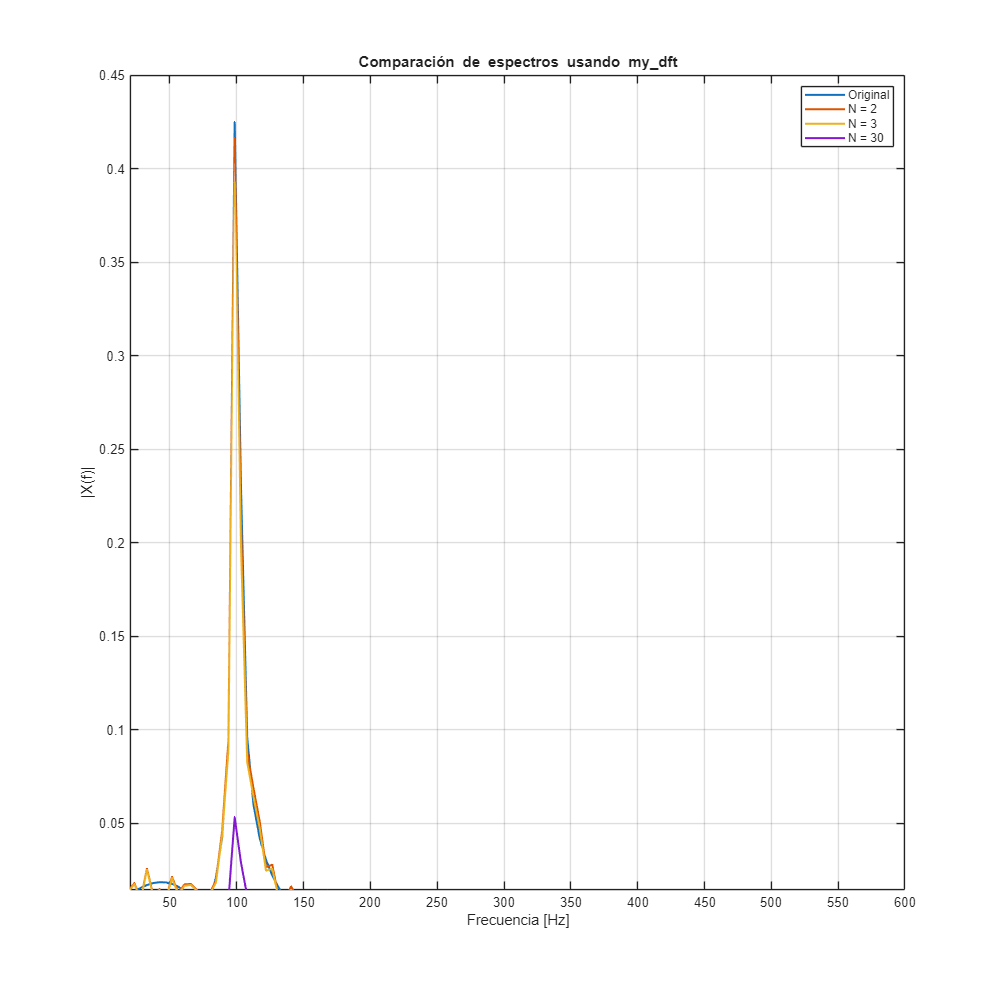

[f_x, mag_x, phase_x, dft_x, NFFT_x] = my_dft(x, freq_s);
[f_half, mag_half, phase_half, dft_half, NFFT_half] = my_dft(filtered_x_half_N_max, freq_s);
[f_full, mag_full, phase_full, dft_full, NFFT_full] = my_dft(filtered_x_N_max, freq_s);
[f_ten, mag_ten, phase_ten, dft_ten, NFFT_ten] = my_dft(filtered_x_ten_N_max, freq_s);

yl = [0 max([mag_x; mag_half; mag_full; mag_ten])];

figure('Position',[100 50 1000 1000]);
plot(f_x, mag_x, 'LineWidth', 1.5); hold on;
plot(f_half, mag_half, 'LineWidth', 1.5);
plot(f_full, mag_full, 'LineWidth', 1.5);
plot(f_ten, mag_ten, 'LineWidth', 1.5);
grid on;
xlim([0 freq_s/4]);
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|');
title('Comparación de espectros usando my\_dft');
legend('Original', ['N = ', num2str(N_half)], ['N = ', num2str(N_max)], ['N = ', num2str(N_ten)]);

### Ejercicio 2